# `Compare: Posteriors versus Segment/Pool Counts.`

`See "Figure2.m" for Data Generation Code.`

## `Configure MATLAB:`

restoredefaultpath;    clear;    close all;    clc;    addpath(genpath(fileparts(mfilename('fullpath')))) % In case "Configure" is not available.
Configure

#### `Choose Data to Load and Visualize:`

Pseudorandom.Seed =  22  ;
nSegmentsALL      = [2  125  5000]             ;
                  % [2  5  25  125  2000  5000];

ShortenDistribution = true    ;
Color.Long          = [0.780 0.039 0.039] ;
Color.Rest          = [0.961 0.467 0.161] ;
Color.Many          = [0.929 0.694 0.125] ;
Color.Prior         = [0.067 0.443 0.745] ;
Color.True          = [0.231 0.667 0.196] ;
MarkerSize          =  4    ;
FontSize            = 18    ;
LineWidth           =  2    ;
StairWidth          =  1    ;
StairStyle          = "-"   ;
yTicks              = [1  2];

if Pseudorandom.Seed == 22;    XLim = [1/8    1/4];
else                      ;    XLim = [ 0      1 ]; % Generic; Distributions will likely overlap at this scale.
end

Figure = figure("Name",'Figure(3)', "Position",[80 80 1280 880]);

if~ShortenDistribution;    Tiles  = tiledlayout(Figure, 2, length(nSegmentsALL), "TileSpacing",'Tight', "Padding",'Compact', "TileIndexing",'ColumnMajor');
else                  ;    Tiles  = tiledlayout(Figure, 6, length(nSegmentsALL), "TileSpacing",'Tight', "Padding",'Compact', "TileIndexing",'ColumnMajor');
end

    Index     = 0           ;
for nSegments = nSegmentsALL
    Index     = Index + 1   ;
  load("Data(Figure=2,Seed="+Pseudorandom.Seed+",nSegments="+nSegments+").mat", "Grid","Long","Rest","Many","Prior","GT", "Summary")

  if nSegments < 4;    Showing = 2;    zoomSamples = Showing * Many.nTimes;    Start = 1              ;    End = Long.nTimes            ;
  else            ;    Showing = 4;    zoomSamples = Showing * Many.nTimes;    Start = Long.nTimes / 2;    End = Start + zoomSamples - 1;
  end

    YLim = [0    80]; % Ad Hoc choice. Could choose from [min([min(.),min('),min(")]),  max([max(.),max('),max(")])] if files were loaded simultaneously.

  if nSegments == nSegmentsALL(1)

    DistributionAxes(Index,:) = ProbabilityPlot(Tiles, Grid, Long,Rest,Many,Prior,GT, XLim, Showing, Color, FontSize, false, YLim, Summary);%YLim);
    if ShortenDistribution
        wasteAxes(1) = nexttile;    wasteAxes(1).XAxis.Color = "None";    wasteAxes(1).YAxis.Color = "None";
        wasteAxes(2) = nexttile;    wasteAxes(2).XAxis.Color = "None";    wasteAxes(2).YAxis.Color = "None";
        wasteAxes(3) = nexttile;    wasteAxes(3).XAxis.Color = "None";    wasteAxes(3).YAxis.Color = "None";
        wasteAxes(4) = nexttile;    wasteAxes(4).XAxis.Color = "None";    wasteAxes(4).YAxis.Color = "None";
    end

  elseif nSegments == nSegmentsALL(2)
    DistributionAxes(Index,:) = ProbabilityPlot(Tiles, Grid, Long,Rest,Many,Prior,GT, XLim, Showing, Color, FontSize, true, YLim, Summary);%YLim);
        wasteAxes(5) = nexttile;    wasteAxes(5).XAxis.Color = "None";    wasteAxes(5).YAxis.Color = "None";
        wasteAxes(6) = nexttile;    wasteAxes(6).XAxis.Color = "None";    wasteAxes(6).YAxis.Color = "None";
        wasteAxes(7) = nexttile;    wasteAxes(7).XAxis.Color = "None";    wasteAxes(7).YAxis.Color = "None";
        wasteAxes(8) = nexttile;    wasteAxes(8).XAxis.Color = "None";    wasteAxes(8).YAxis.Color = "None";
  else
    DistributionAxes(Index,:) = ProbabilityPlot(Tiles, Grid, Long,Rest,Many,Prior,GT, XLim, Showing, Color, FontSize, false, YLim, Summary);%YLim);

  end
end

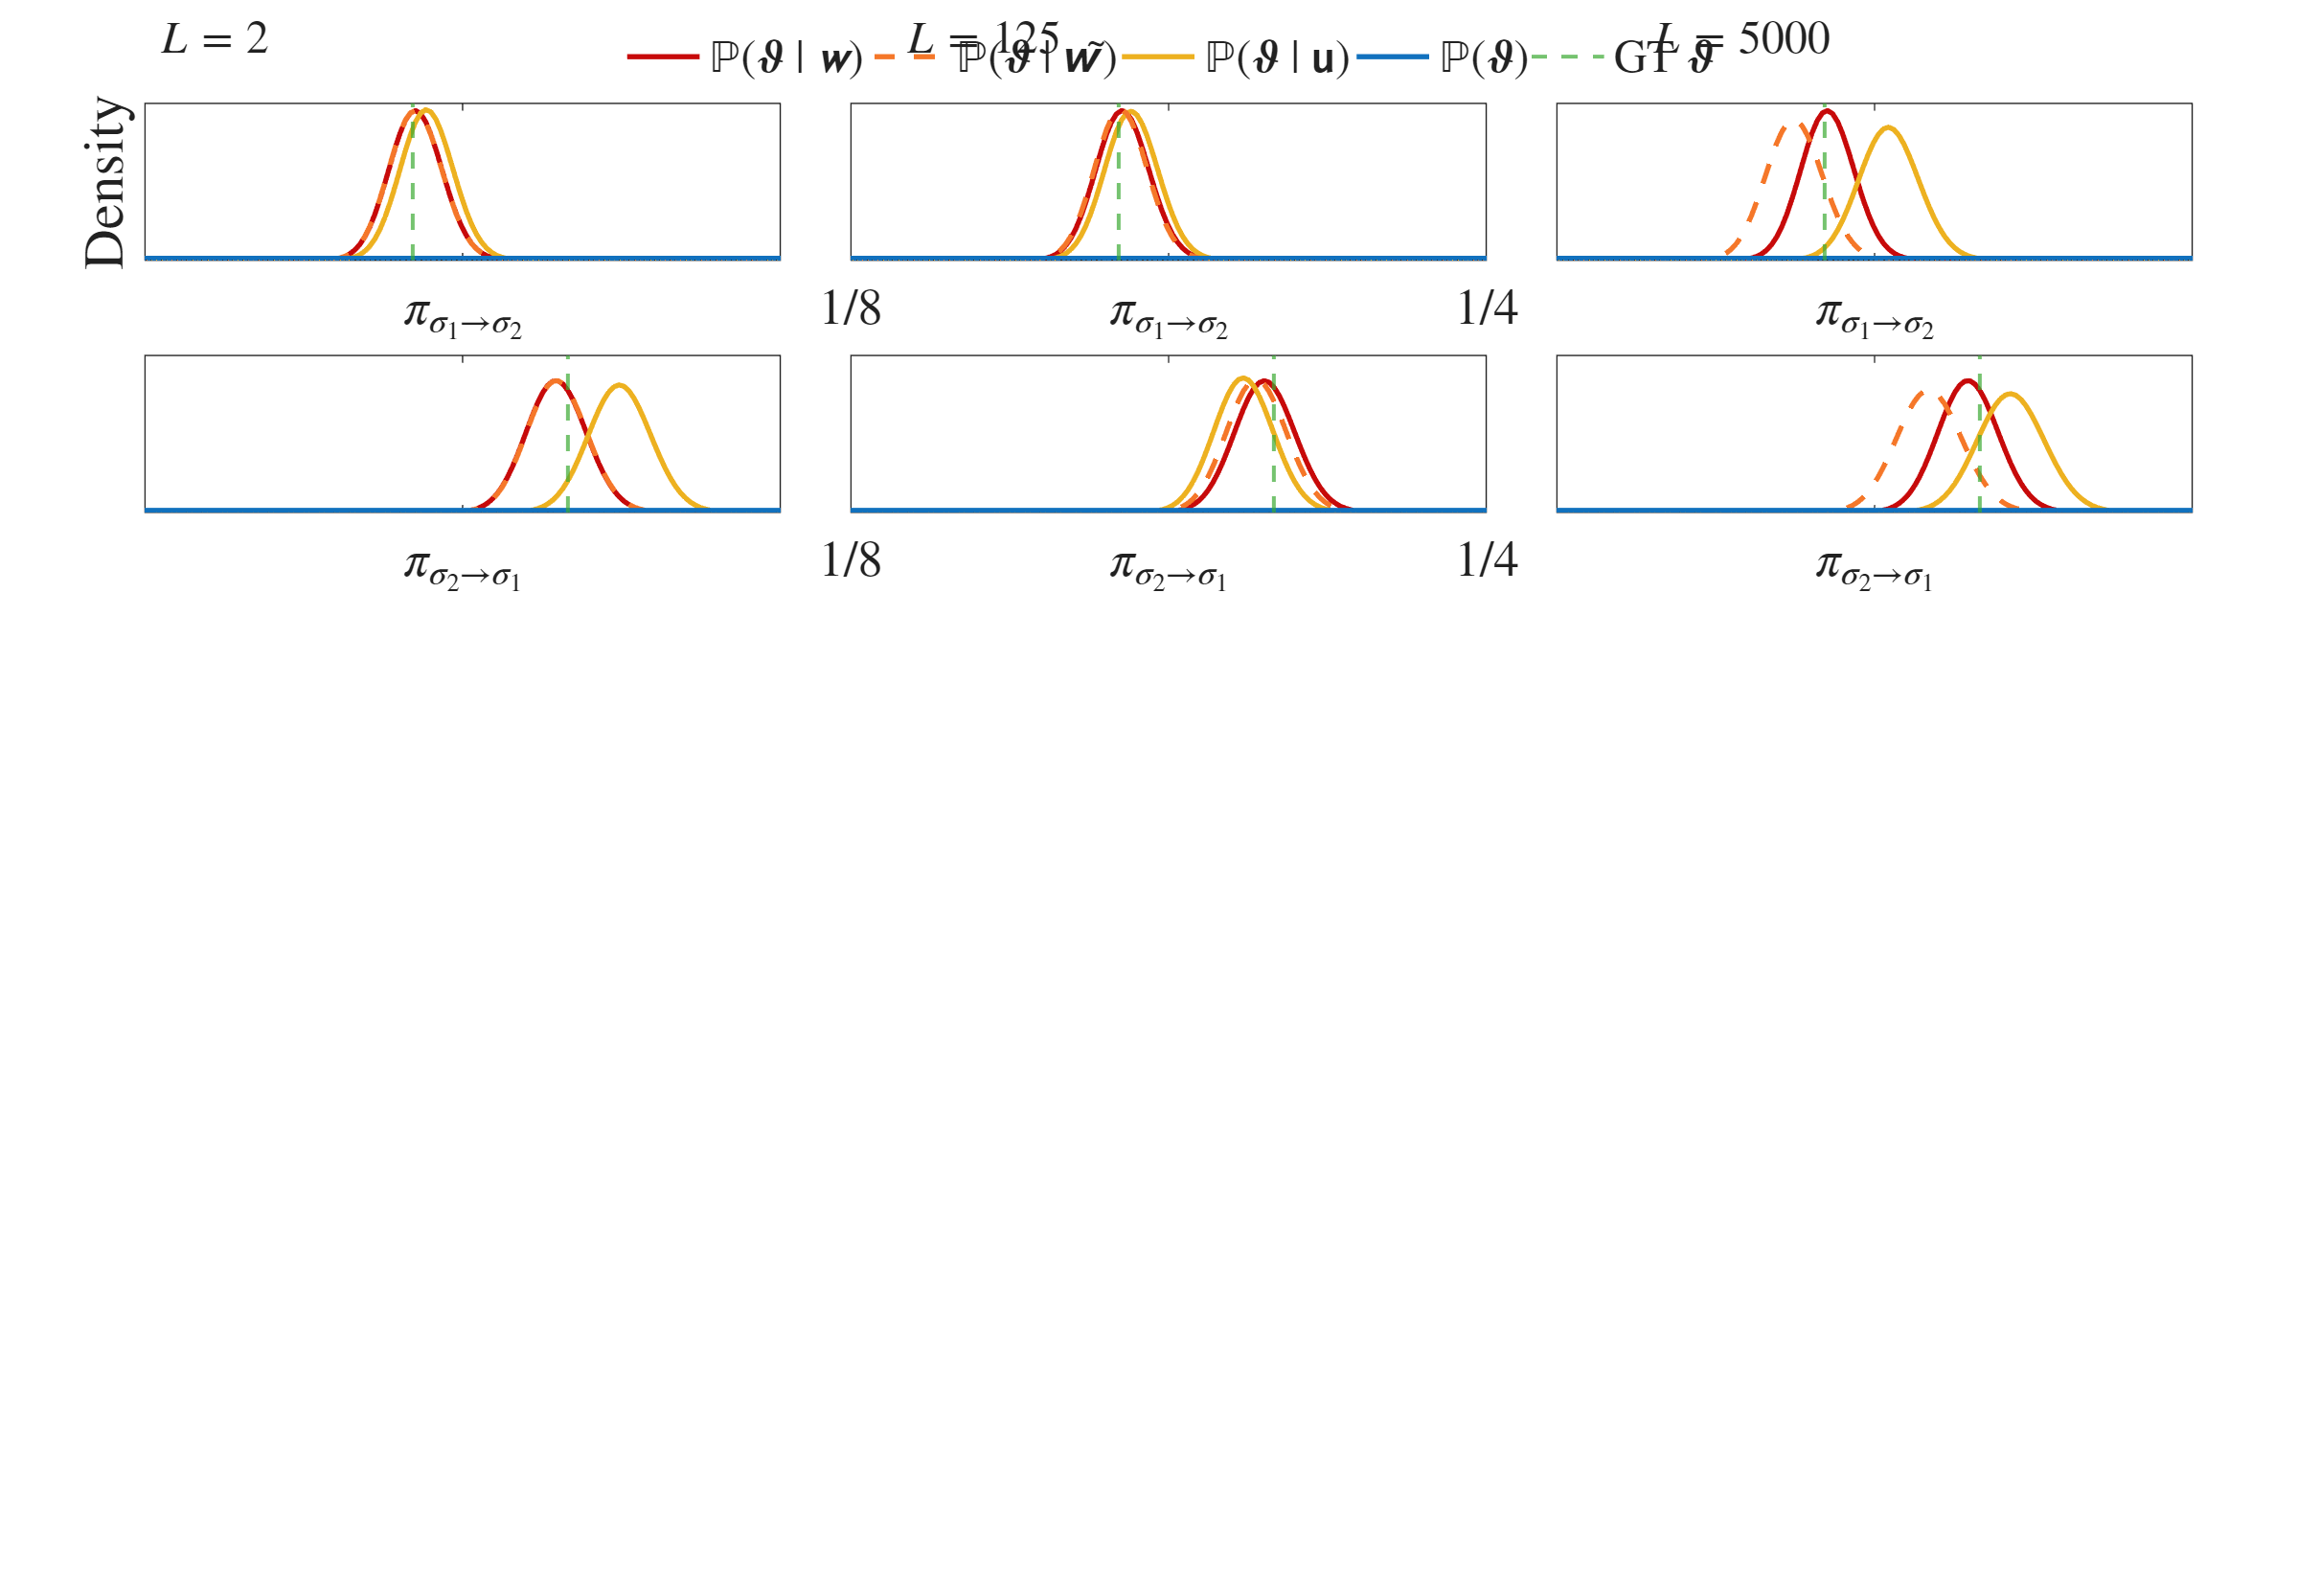

% Turn off XTicks and Labels away from Central Plot.
for Index = [1,3]
    DistributionAxes(Index,1).XTickLabels{1} = "";
    DistributionAxes(Index,1).XTickLabels{3} = "";

    DistributionAxes(Index,2).XTickLabels{1} = "";
    DistributionAxes(Index,2).XTickLabels{3} = "";
end

for Index = 2:3
    DistributionAxes(Index,1).YLabel.String = {};
    DistributionAxes(Index,1).YTickLabels   = {};

    DistributionAxes(Index,2).YLabel.String = {};
    DistributionAxes(Index,2).YTickLabels   = {};
end

DistributionAxes(2,1).Legend.Orientation = "Horizontal"  ;
DistributionAxes(2,1).Legend.Location    = "NorthOutside";

for Index = 1 : 3;    Text(Index) = text(DistributionAxes(Index,1), 0,1.05, " $L="+nSegmentsALL(Index)+"$", "Units",'Normalized', "HorizontalAlignment",'Left', "VerticalAlignment","Top", "FontSize",FontSize);    end


%{
% Turn off "Density" from Top row.
DistributionAxes(1,1).YLabel.String   = "";
% Apply "Density" to Full Graph.
ylabel(Tiles, "Density", "Interpreter",'LaTeX', "FontSize",FontSize+2)
%}

print("Figure(3,L="+nSegmentsALL+")", "-dpng","-r350")

### `Probability Plots:`

function distributionAxes = ProbabilityPlot(Tiles, Grid, Long,Rest,Many,Prior,GT, XLim, Showing, Color, FontSize, Legend, YLim, Summary)
  distributionAxes(1) = nexttile(Tiles);
  hold(distributionAxes(1),"On");
  Plot.Long  = plot(distributionAxes(1), Grid.p, Long.logPosterior.p, "LineWidth",2, "Color",Color.Long, "DisplayName","ℙ(𝝑 | 𝙬)");
  Plot.Many  = plot(distributionAxes(1), Grid.p, Many.logPosterior.p, "LineWidth",2, "Color",Color.Many, "DisplayName","ℙ(𝝑 | 𝘂)");
  Plot.LongR = plot(distributionAxes(1), Grid.p, Rest.logPosterior.p, "LineWidth",2, "Color",Color.Rest, "LineStyle",'--', "DisplayName","ℙ(𝝑 | 𝙬͂)");
  
  Plot.Prior = plot(distributionAxes(1), Grid.p, Prior.p,             "LineWidth",2, "Color",Color.Prior, "DisplayName","ℙ(𝝑)");
  Plot.True  = xline(distributionAxes(1), GT.p, '--', "Color",Color.True, "LineWidth",3/2, "DisplayName","GT 𝝑");

  ylabel(distributionAxes(1),"Density","Interpreter",'LaTeX');
 
if Legend;    legend(distributionAxes(1), [Plot.Long,Plot.LongR,Plot.Many,Plot.Prior,Plot.True], "Location",'NorthEast', "Box",'Off', "AutoUpdate",'Off');    end

  distributionAxes(1).XLim                       = XLim                                                                 ;
  distributionAxes(1).XTick                      = linspace(distributionAxes(1).XLim(1), distributionAxes(1).XLim(2), 3);
  distributionAxes(1).XTickLabel(floor(end/2)+1) = {"$\pi_{\sigma_{1}\to\sigma_{2}}$"}                                  ;  

if~isempty(YLim)
  distributionAxes(1).YLim  = YLim;
end
  distributionAxes(1).YTick = linspace(distributionAxes(1).YLim(1), distributionAxes(1).YLim(2), 2);
  
        distributionAxes(2) = nexttile(Tiles);
  hold (distributionAxes(2),"On");
  plot (distributionAxes(2), Grid.q, Long.logPosterior.q, "LineWidth",2, "Color",Color.Long);
  plot (distributionAxes(2), Grid.q, Rest.logPosterior.q, "LineWidth",2, "Color",Color.Rest, "LineStyle",'--', "DisplayName","ℙ(𝝑 | 𝙬͂)");
  plot (distributionAxes(2), Grid.q, Many.logPosterior.q, "LineWidth",2, "Color",Color.Many);
  plot (distributionAxes(2), Grid.q, Prior.q,             "LineWidth",2, "Color",Color.Prior);
  xline(distributionAxes(2), GT.q, '--', "Color",Color.True, "LineWidth",3/2);

  distributionAxes(2).XLim                       = XLim                                                                 ;
  distributionAxes(2).XTick                      = linspace(distributionAxes(2).XLim(1), distributionAxes(2).XLim(2), 3);
  distributionAxes(2).XTickLabel(floor(end/2)+1) = {"$\pi_{\sigma_{2}\to\sigma_{1}}$"}                                  ;

if~isempty(YLim)
  distributionAxes(2).YLim  = YLim;
end
  distributionAxes(2).YTick = linspace(distributionAxes(2).YLim(1), distributionAxes(2).YLim(2), 2);

  grid(distributionAxes(1), "Off");
  grid(distributionAxes(2), "Off");

  distributionAxes(1).FontSize = FontSize + 2;
  distributionAxes(2).FontSize = FontSize + 2;
  
%%%%%     %%%%%     %%%%%     %%%%%     %%%%% 
% For xLim=[1/8    1/4] only.
  distributionAxes(1).XTickLabel(1) = {"1/8"};
  distributionAxes(2).XTickLabel(1) = {"1/8"};
  
  distributionAxes(1).XTickLabel(3) = {"1/4"};
  distributionAxes(2).XTickLabel(3) = {"1/4"};
%%%%%     %%%%%     %%%%%     %%%%%     %%%%%     

  distributionAxes(1).YTick = distributionAxes(2).YTick;

  distributionAxes(1).YTickLabel = {""};
  distributionAxes(2).YTickLabel = {""};

  distributionAxes(1).Box = "On";
  distributionAxes(2).Box = "On";
end
